# Rufous Robust Attitude and Angular Rate Controller with Multiplicative Input Uncertainty

## Parameters

close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
ht = sqrt(g * mass / (Kt * 4));

RUFOUS_N_INPUTS = 4;			% number of inputs
RUFOUS_N_STATES = 6;			% number of states
RUFOUS_STATE_DIM = 3;			% dimension of each state

## Attitude Plant

I = eye(RUFOUS_STATE_DIM);
O = zeros(RUFOUS_STATE_DIM, RUFOUS_STATE_DIM);

tau_k = [1  0 -1  0;		% Alter this to effect the sensitivity of input -> state channels
	     0 -1  0  1;
		-1  1 -1  1];

A = [O I;				    % block size (state_dim, state_dim)
	 O O];
B = Kt *[zeros(RUFOUS_STATE_DIM, RUFOUS_N_INPUTS); Ib^-1 * l * tau_k * 2 * ht];		% block size (state_dim, n_inputs) ignore non-controlled forces
C = eye(RUFOUS_N_STATES);
D = 0;

G = ss(A, B, C, D);

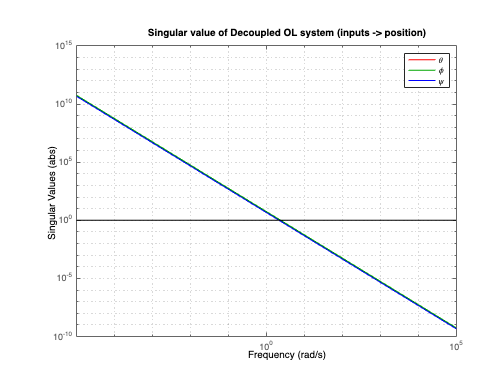

freq_range = [1e-5 1e5];

% Without a control law X and Y will not appear
figure, hold on, grid minor
h = sigmaplot(G(1, :), 'r', G(2, :), 'g', G(3, :), 'b', freq_range);
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log')
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> position)")
legend("\theta", "\phi", "\psi")

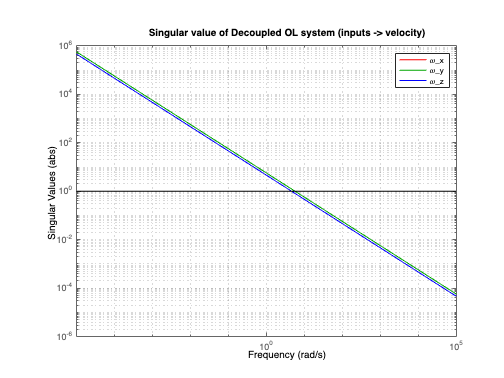


figure, hold on, grid minor
h = sigmaplot(G(4, :), 'r', G(5, :), 'g', G(6, :), 'b', freq_range);
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log')
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> velocity)")
legend("\omega_x", "\omega_y", "\omega_z")

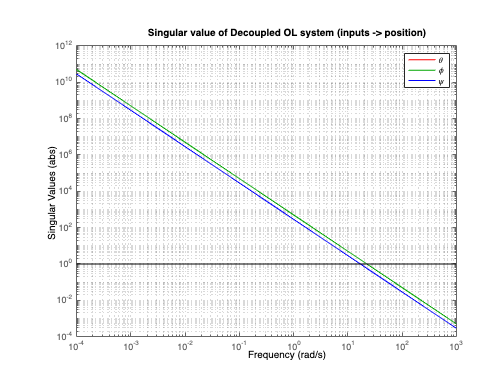

freq_range = [1e-4 1e3];

z = [0; 0; 1];
Z = [z z z z];
Xo = [0; 0; 0];
Uo = [0; 0; 0; 0];
Ht = [ht; ht; ht; ht];
I = eye(RUFOUS_STATE_DIM);
O = zeros(RUFOUS_N_INPUTS, RUFOUS_STATE_DIM);

% [Kref, Kfb, Kff] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 40, 75, 0.1, 1, 50);
[Kref, Kfb, ~] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 75, 100, 0.08, 0.5, 15);

K = ss(Kfb(:,7:end));
L = G * K;

figure, hold on, grid minor
h = sigmaplot(L(1, :), 'r', L(2, :), 'g', L(3, :), 'b', linspace(freq_range(1), freq_range(2))); % 
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log') % , 'Ylim', mag_range
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> position)")
legend("\theta", "\phi", "\psi")

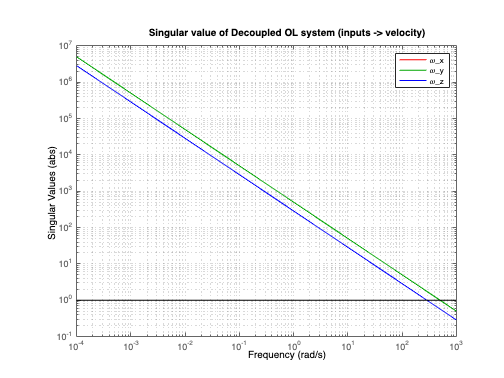


figure, hold on, grid minor
h = sigmaplot(L(4, :), 'r', L(5, :), 'g', L(6, :), 'b', linspace(freq_range(1), freq_range(2)));
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log')
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> velocity)")
legend("\omega_x", "\omega_y", "\omega_z")

freq_range = [1e-10 1e4];

% Test previously designed control law
Katt = 75 * pinv(tau_k);
Krate = 100 * pinv(tau_k);

K = ss([Katt Krate]);
L = G * K;
S = 1 / (eye(RUFOUS_N_STATES) + L);
T = minreal(L * S);

6 states removed.



WI = makeweight(0.01, [2, 1], 10) * eye(RUFOUS_N_STATES);
WP = makeweight(0.1, [1, 1], 100) * eye(RUFOUS_N_STATES);

Hinf_norm_s = norm(S, 'inf')

Hinf_norm_s = 1.6667

Hinf_norm_t = norm(T, 'inf')

Hinf_norm_t = Inf

Hinf_norm_n11 = norm(WI * T, 'inf')

Hinf_norm_n11 = Inf

Hinf_norm_n22 = norm(WP * T, 'inf')

Hinf_norm_n22 = Inf

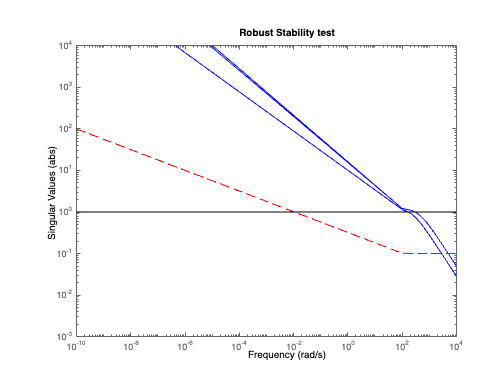


figure, hold on
h = sigmaplot(T, 'b', WI^-1, 'r--', linspace(freq_range(1), freq_range(2)));
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log', 'Ylim', [1e-3 1e4]);
title("Robust Stability test")

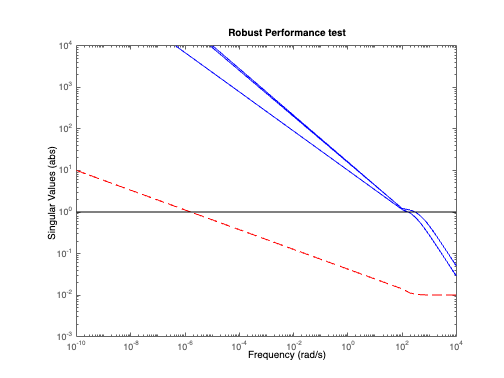


figure, hold on
h = sigmaplot(T, 'b', WP^-1, 'r--', linspace(freq_range(1), freq_range(2)));
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log', 'Ylim', [1e-3 1e4]);
title("Robust Performance test")

freq_range = [1e-10 1e4];

systemnames = 'G WP';
inputvar = '[qr(6); u(4)]';
outputvar = '[WP; qr-G]';
input_to_G = '[u]';
input_to_WP = '[qr-G]';
sysoutname = 'P';
sysic;
P_nominal = minreal(ss(P));

[K, ~, ~] = hinfsyn(P_nominal, 6, 4);

L = G * K;
S = 1 / (eye(RUFOUS_N_STATES) + L);
T = minreal(L * S);

8 states removed.


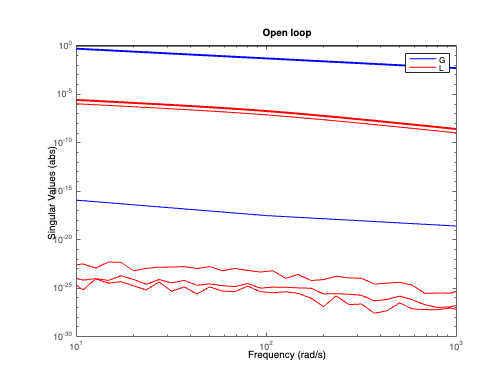


WP = makeweight(0.01, [1, 1], 5) * eye(RUFOUS_N_STATES);

figure, hold on
h = sigmaplot(G, 'b', L, 'r');
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log');
title("Open loop")
legend("G", "L")

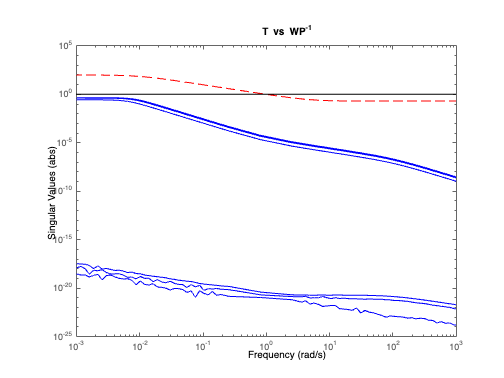


figure, hold on
h = sigmaplot(T, 'b', WP^-1, 'r--');
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log');
title("T vs WP^{-1}")

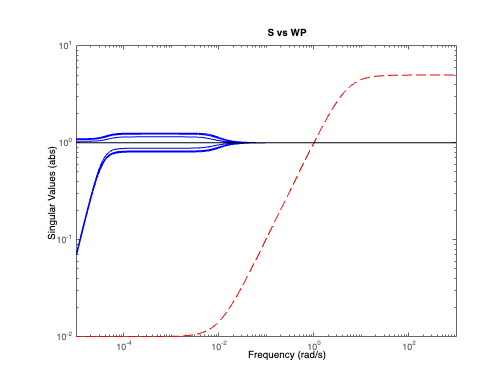


figure, hold on
h = sigmaplot(S, 'b', WP, 'r--');
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log');
title("S vs WP")

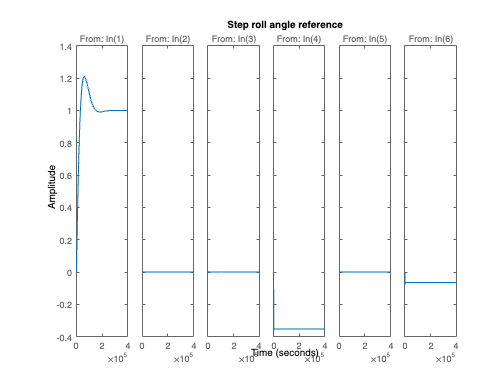


figure
step(T(1,1:6))
title("Step roll angle reference")

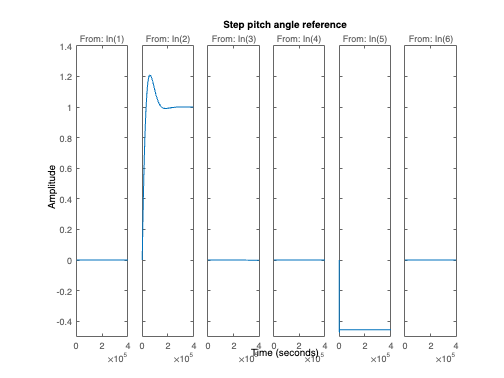

figure
step(T(2,1:6))
title("Step pitch angle reference")

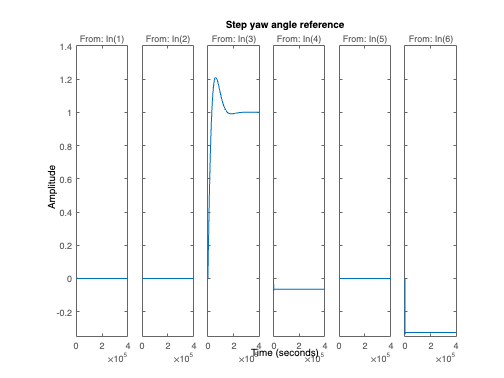

figure
step(T(3,1:6))
title("Step yaw angle reference")

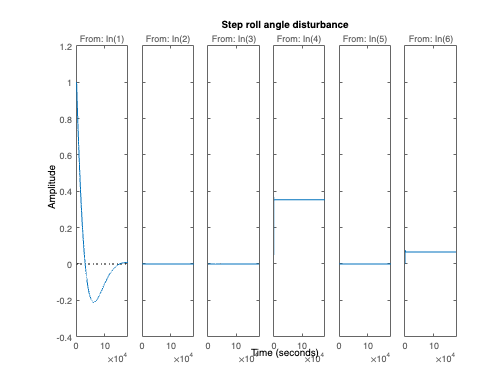


figure
step(S(1,1:6))
title("Step roll angle disturbance")

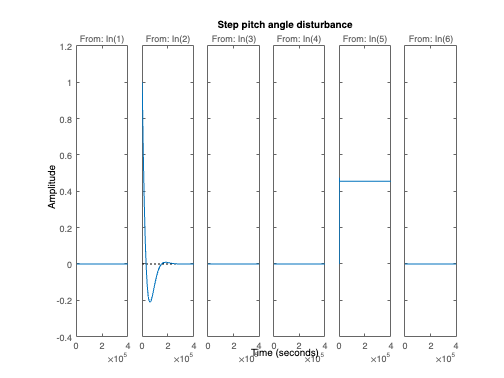

figure
step(S(2,1:6))
title("Step pitch angle disturbance")

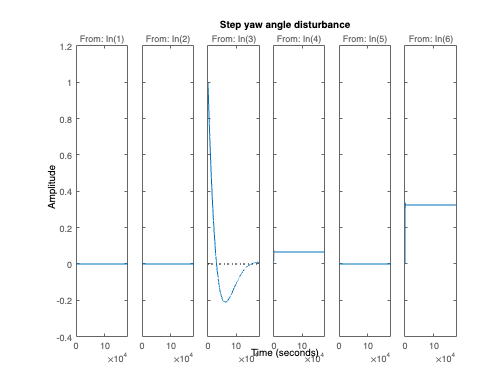

figure
step(S(3,1:6))
title("Step yaw angle disturbance")

WP = makeweight(0.01, [1, 0.1], 1) * eye(RUFOUS_N_STATES);
WI = (s + 0.2) / ((0.5 * s) + 1) * eye(RUFOUS_N_STATES);

systemnames = 'G WP';
inputvar = '[qr(6); u(4)]';
outputvar = '[WP; qr-G]';
input_to_G = '[u]';
input_to_WP = '[qr-G]';
input_to_WI = '[u]';
sysoutname = 'P';
sysic;

[K, ~, ~] = hinfsyn(P, 6, 4);

L = G * K;
S = 1 / (eye(RUFOUS_N_STATES) + L);
T = minreal(L * S);

13 states removed.



s = tf('s');
N11 = -WI * T;
N22 = WP * (eye(RUFOUS_N_STATES) - T);
BlkStruct = [RUFOUS_N_STATES 0];
N11_frd = frd(N11, logspace(-5,5));
N22_frd = frd(N22, logspace(-5,5));
[mubnds_sability] = mussv(N11_frd, BlkStruct);

Points completed: 50/50


[mubnds_performance] = mussv(N22_frd, BlkStruct);

Points completed: 50/50


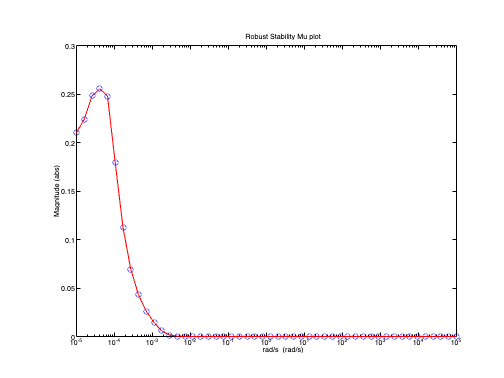


LinMagopt = bodeoptions;
LinMagopt.PhaseVisible = 'off';
LinMagopt.MagUnits = 'abs';

figure, clf
bodeplot(mubnds_sability(1, 1), 'bo', mubnds_sability(1, 2), 'r-', LinMagopt)
xlabel('rad/s');
ylabel('Mu upper/lower bounds')
title("Robust Stability Mu plot")

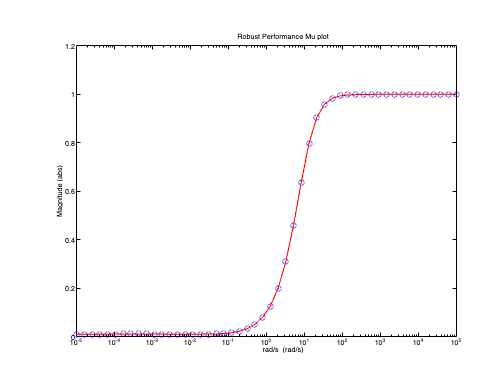


figure, clf
bodeplot(mubnds_performance(1, 1), 'bo', mubnds_performance(1, 2), 'r-', LinMagopt)
xlabel('rad/s');
ylabel('Mu upper/lower bounds')
title("Robust Performance Mu plot")

WP = makeweight(0.01, [1, 0.1], 1) * eye(RUFOUS_N_STATES);
WI = (s + 0.2) / ((0.5 * s) + 1) * eye(RUFOUS_N_INPUTS, RUFOUS_N_INPUTS);

systemnames = 'G WP WI';
inputvar = '[ydel(4); qr(6); u(4)]';
outputvar = '[WI; WP; qr-G]';
input_to_G = '[u+ydel]';
input_to_WP = '[qr-G]';
input_to_WI = '[u]';
sysoutname = 'P';
sysic;

N = 10;
omega = logspace(-5,5);
Blk = [RUFOUS_N_INPUTS 0];
D = append(1, 1, 1, 1, tf(eye(RUFOUS_N_STATES)), tf(eye(RUFOUS_N_STATES)));
pD = append(1, 1, 1, 1, tf(eye(RUFOUS_N_STATES)), tf(eye(RUFOUS_N_INPUTS)));

[K, ~, ~] = hinfsyn(D * P * pD, 6, 4);

Nf = frd(lft(P,K), omega);
[mu_Nf, mu_Info] = mussv(Nf, Blk);

Error using mussvcalc2
The dimensions of matrix are incompatible with the BLK dimensions.

Error in mussv (line 193)
         [varargout{1:max(1,nargout)}] = mussvcalc2(matin,blk,varargin{:});


L = G * K;
S = 1 / (eye(RUFOUS_N_STATES) + L);
T = minreal(L * S);

mu_RP = zeros(N);
mu_RP(1) = norm(mu_Nf(1,1), 'inf', 1e-6);

figure
for i = 2:N
    [dsysl, dsysr] = mussvunwrap(mu_Info);
    dsysl = dsysl/dsysl(3,3);
    di = fitfrd(genphase(dsysl(1,1)), 3);
%     D = append(di, di, di, di, tf(eye(RUFOUS_N_STATES)), tf(eye(RUFOUS_N_STATES)));
%     pD = append(di, di, di, di, tf(eye(RUFOUS_N_INPUTS)), tf(eye(RUFOUS_N_INPUTS)));

    [K, ~, ~] = hinfsyn(D * P * pD, 6, 4);

    Nf = frd(lft(P,K), omega)
    [mu_Nf, mu_Info] = mussv(Nf, Blk);
    mu_RP(i) = norm(mu_Nf(1,1), 'inf', 1e-6);

    bodeplot(mu_NF(1,1), LinMagopt);
    pause(0.001)

    if i == N
        Kfinal = Ki;
    end
end